## Cell array : how to construct cell array, manipulate and display them

clear;
clc;            % Clean up workspace and current screen

% Construct a cell array
String = char('This is ', 'an instance of cell array.');
Real_Matrix = reshape(1:9, 3, 3);
Complex = [1 + 2i];
Function_Symbol = sym('sin(-3*t) * exp(-t^2)');

MyCellArray(1, 1) = {String};             % Row 1, Col. 1
MyCellArray(1, 2) = {Real_Matrix};        % Row 1, Col. 2
MyCellArray(2, 1) = {Complex};            % Row 2, Col. 1
MyCellArray(2, 2) = {Function_Symbol};    % Row 2, Col. 2
MyCellArray     % Just display the structure of cell array

MyCellArray =     [2×26 char]    [3×3 double]
    [1.0000 + 2.0000i]    [1×1 sym   ]


celldisp(MyCellArray)    % Show the actual content of cell array

 
MyCellArray{1,1} =
 
This is                   
an instance of cell array.
 
 
MyCellArray{2,1} =
 
   1.0000 + 2.0000i

 
 
MyCellArray{1,2} =
 
     1     4     7
     2     5     8
     3     6     9

 
 
MyCellArray{2,2} =
 


$$-\sin\left(3\,t\right)\,{\mathrm{e}}^{-t^{2}}$$


CellArray = cell(2, 2);            % Pre-construct a (2 x 2) cell array, but it is empty now.
CellArray(:, 1) = {char('Another', 'tet string')};    % Assign the 1st column cells.
CellArray

CellArray =     [2×10 char]    []
    [2×10 char]    []



% Extend the cell array in row and column direction respectively.
ExtendedCellArray_inColumn = [CellArray, MyCellArray]    % NOTE : the , is used to separate columns

ExtendedCellArray_inColumn =     [2×10 char]    []    [2×26 char]    [3×3 double]
    [2×10 char]    []    [1.0000 + 2.0000i]    [1×1 sym   ]


ExtendedCellArray_inRow    = [CellArray; MyCellArray]    % NOTE : the ; is used to separate rows

ExtendedCellArray_inRow =     [2×10 char]              []
    [2×10 char]              []
    [2×26 char]    [3×3 double]
    [1.0000 + 2.0000i]    [1×1 sym   ]


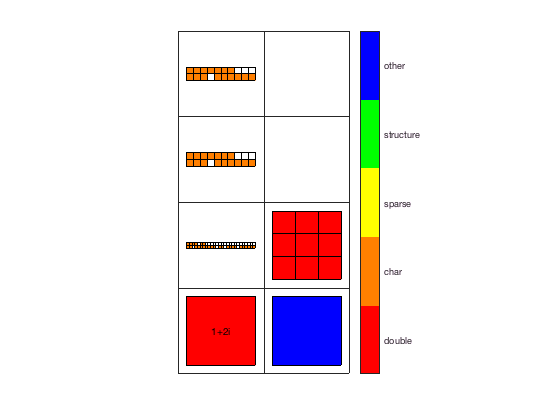

cellplot(ExtendedCellArray_inRow, 'legend')    % Plot the diagram to visualize the cell array

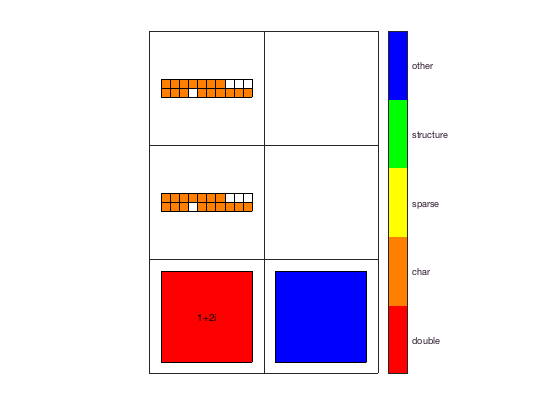

% Narrow the cell array
ExtendedCellArray_inRow(3, :) = [];    % Remove the cells in row 3
cellplot(ExtendedCellArray_inRow, 'legend')

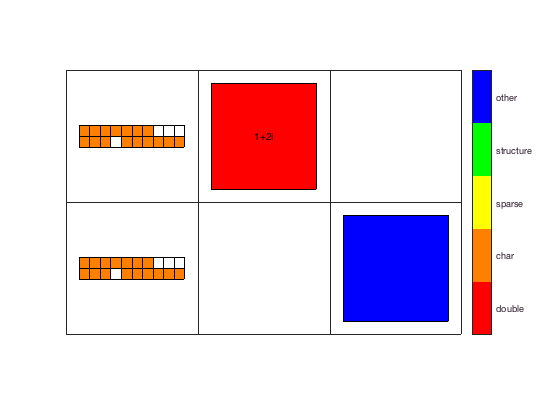

ReconstructCellArray = reshape(ExtendedCellArray_inRow, 2, 3);    % Reconstruct the cell array from 3_rows * 2_cols to 2_rows * 3_cols
cellplot(ReconstructCellArray, 'legend')